# Develop differential equations for a gantry crane

clear variables

results_dir = 'results';
if ~isfolder(results_dir)
    mkdir(results_dir)
end

## Description of system

The equations below were developed from the cart-pole equations presented by:

- R. V. Florian, 2007, Correct equations for the dynamics of the cart-pole system.

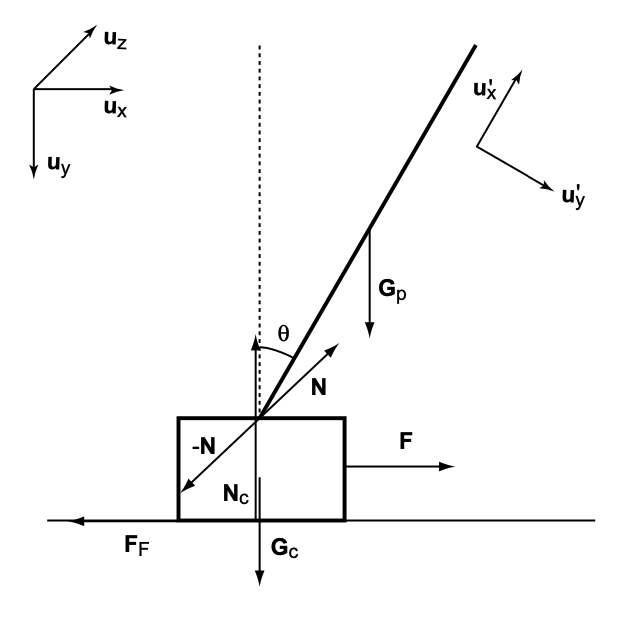

Note: I will replace ${{\mathbf{u}}^{\prime } }_x$ and ${{\mathbf{u}}^{\prime } }_y$ with ${\mathbf{u}}_r$ and ${\mathbf{u}}_t$ below to avoid confusion.

State variables

- Horizontal position of cart (from left) $x\left(t\right)$

- Horizontal velocity of cart $\dot{x} \left(t\right)$

- Angle of arm (clockwise from vertical up position) $\theta \left(t\right)$

- Angular velocity of cable$\dot{\;\theta \;} \left(t\right)$ (clockwise)

Other variables

- Upwards force on cart by track $N_c \left(t\right)$ (+ve upwards)

- Force exerted on arm by cart in x-direction $N_x \left(t\right)$ (+ve to right)

- Upwards force exerted on arm by cart (opposite to y-direction) $N_y \left(t\right)$ (+ve updards)

- Frictional force exerted on cart by track $F_f \left(t\right)$ (+ve to left)

- Aerodynamic drag force on load opposite to x-direction $F_{d,x} \left(t\right)$(+ve to left)

- Aerodynamic drag force on load opposite to y-direction $F_{d,y\;} \left(t\right)$(+ve upwards)

Potential manipulatable input variables

- Horizontal driving force on cart $F\left(t\right)$

Potential disturbance input variables

- Horizontal wind velocity $v_{w,x} \left(t\right)$ - NOT YET IMPLEMENTED

Parameters

- Arm length $L$

- Cart mass $m_c$

- Load mass $m_p$

- Acceleration due to gravity $g$

- Coefficient of friction for cart on track $\mu_c$

- Radius of the load, $r$ (if it were a sphere)

- Aerodynamic drag coefficient of load $c_d$

- Mass density of air $\rho_a$

## Derivation of equations

% Define symbolic variables
syms x(t) theta(t) N_c(t) F(t) F_f(t) F_d(t) Nx(t) L m_c m_p g muc r c_d rho

Co-ordinate systems:

    ${\mathbf{u}}_x ,{\mathbf{u}}_y$: unit vectors in the x direction (to the right), and y direction (down).

    ${\mathbf{u}}_r ={\mathbf{u}}_x \sin \theta -{\mathbf{u}}_y \cos \theta \;,{\mathbf{u}}_t ={\mathbf{u}}_x \cos \theta +{\mathbf{u}}_y \sin \theta$: unit vectors in direction of pole (radially outwards) and perpendicular to pole (clockwise tangentially)

Force balance on cart (cartesian vectors):

    $\mathbf{F}+{\mathbf{F}}_f +{\mathbf{G}}_c -\mathbf{N}+{\mathbf{N}}_c =m_c {\mathbf{a}}_c$                                   (3)

where:

    $\mathbf{F}=F{\mathbf{u}}_x$: external force applied to cart (to the right)

    ${\mathbf{F}}_f =-F_f {\mathbf{u}}_x$: friction force on cart due to track (to the left when $F_f$ is +ve)

    ${\mathbf{G}}_c =m_c g{\mathbf{u}}_y$: downwards force due to weight of cart

    $\mathbf{N}=N_x {\mathbf{u}}_x -N_y {\mathbf{u}}_y$: force on pole due to cart (upwards and to right when $N_x$ and $N_y$ are +ve)

    ${\mathbf{N}}_c ={-N}_c {\mathbf{u}}_y$: Force on cart by track (upwards when $N_c$ is +ve)

    ${\mathbf{a}}_c =\ddot{x} {\mathbf{u}}_x$ : acceleration of cart

Decompose (3) into x, y directions:

    $F-F_f -N_x =m_c \ddot{x}$                                                    (4)

    $m_c g+N_y -N_c =0$                                                    (5)

Coulomb friction model:

    $F_f =\mu_c |N_c |\textrm{sign}\left(\dot{x} \right)=\mu_c N_c \textrm{sign}\left(N_c \dot{x} \right)$                        (6)

% Friction force of track on cart (to the left when F_f(t) is positive)
eqn1 = F_f(t) == muc * N_c * sign(N_c * diff(x(t)))

$$eqn1(t) = F_{f}\left(t\right)=\mathrm{muc}\,\mathrm{sign}\left(N_{c}\left(t\right)\,\frac{\partial }{\partial t}x\left(t\right)\right)\,N_{c}\left(t\right)$$

Force balance on pole (cartesian vectors):

    $\mathbf{N}+{\mathbf{F}}_d +{\mathbf{G}}_p =m_p {\mathbf{a}}_p$                                                         (7)

where:

    ${\mathbf{F}}_d =-F_{d,x} {\mathbf{u}}_x -F_{d,y} {\mathbf{u}}_y$ : Aerodynamic drag force on load (in opposite direction to velocity of load relative to air)

    ${\mathbf{G}}_p =m_p g{\mathbf{u}}_y$ : weight of load (downwards)

    ${\mathbf{a}}_p$ : acceleration of the load

Absolute magnitude of drag force on load:

    
$$F_d =\frac{1}{2}\rho {|\mathbf{v}|}^2 c_d A=\frac{1}{2}\rho c_d A\left({\left(v_x +v_{w,x} \right)}^2 +v_y^2 \right)$$


where

    $\mathbf{v}=\left(v_x +v_{w,x} \right){\mathbf{u}}_x +v_y {\mathbf{u}}_y$: velocity of the load through the air

and

    
$$\begin{array}{l}
v_x =\dot{x} +L\dot{\theta} \cos \theta \;\\
v_y =L\dot{\theta} \sin \theta 
\end{array}$$


% x and y components of velocity of load through the air
v_x = diff(x(t)) + L * diff(theta(t)) * cos(theta(t));
v_y = L * diff(theta(t)) * sin(theta(t));


$$F_{d,x} =\frac{1}{2}\rho c_d Av_x^2 =\frac{1}{2}\rho c_d {A\left(\dot{x} +\dot{L} \sin \theta +L\dot{\theta} \cos \theta \right)}^2$$



$$F_{d,y} =\frac{1}{2}\rho c_d Av_y^2 =\frac{1}{2}\rho c_d {A\left(\dot{L} \cos \theta +L\dot{\theta} \sin \theta \right)}^2$$


% Magnitudes of x and y components of drag force on load
F_dx = 0.5 * rho * c_d * pi * r^2  * v_x^2;  % TODO: Add wind as per above eqns
F_dy = 0.5 * rho * c_d * pi * r^2  * v_y^2;
% Absolute magnitude of aerodynamic drag force
eqn2 = F_d(t) == 0.5 * rho * c_d * pi * r^2 * (v_x^2 + v_y^2)

$$eqn2 = F_{d}\left(t\right)=1.5708\,c_{d}\,r^{2}\,\rho \,\left({\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}L\left(t\right)+\frac{\partial }{\partial t}x\left(t\right)+\cos\left(\theta \left(t\right)\right)\,L\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+{\left(\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}L\left(t\right)+\sin\left(\theta \left(t\right)\right)\,L\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)$$

The acceleration of the load is due to the composed effects of:

- acceleration of cart

- acceleration due to rotation of pole with angular velocity $\omega =\dot{\theta} {\mathbf{u}}_z$

- angular acceleration of the pole $\varepsilon =\ddot{\theta} {\mathbf{u}}_z$

    ${\mathbf{a}}_p ={\mathbf{a}}_c +\varepsilon \times {\mathbf{r}}_p +\omega \times \left(\omega \times {\mathbf{r}}_p \right)$                            (8)

where:

    ${\mathbf{r}}_p =L\left(\sin \theta {\mathbf{u}}_y -\cos \theta {\mathbf{u}}_x \right)$ : position of centre of load relative to the pivot

Substitute (8) into (7) and decompose into x and y directions:

    $N_x +F_{d,x} =m_p \left(\ddot{x} +L\ddot{\theta} \cos \theta -L{\dot{\theta} }^2 \sin \theta \right)$                    (11)

% Horizontal (x) component of force on pole by cart
N_x(t) = sign(v_x) * F_dx + m_p * ( diff(x(t), 2) + L * diff(theta(t), 2) * cos(theta(t)) - L * diff(theta(t))^2 * sin(theta(t)) )

$$N\_x(t) = \begin{array}{l} m_{p}\,\left(\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-\sin\left(\theta \left(t\right)\right)\,L\left(t\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\cos\left(\theta \left(t\right)\right)\,L\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\right)+1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sign}\left(\sigma_{1}\right)\,{\sigma_{1}}^{2}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}L\left(t\right)+\frac{\partial }{\partial t}x\left(t\right)+\cos\left(\theta \left(t\right)\right)\,L\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}$$

    $m_p g-N_y +F_{d,y} =m_p \left(L\ddot{\theta} \sin \theta +L{\dot{\theta} }^2 \cos \theta \right)$                (12)

% Vertical (y) component of force on pole by cart
N_y(t) = -sign(v_y) * F_dy - m_p * g - m_p * L * ( diff(x(t), 2) * sin(theta(t)) + diff(theta(t), 2) * cos(theta(t)) )

$$N\_y(t) = \begin{array}{l} -g\,m_{p}-m_{p}\,L\left(t\right)\,\left(\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\right)-1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sign}\left(\sigma_{1}\right)\,{\sigma_{1}}^{2}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}L\left(t\right)+\sin\left(\theta \left(t\right)\right)\,L\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}$$

Torque Balance of pole:

    
$$\mathbf{M}=\mathbf{I}\varepsilon +{\mathbf{r}}_p \times {\mathbf{a}}_c$$


where:

    $\mathbf{M}={\mathbf{r}}_p \times {\mathbf{G}}_p -{\mathbf{r}}_p \times {\mathbf{F}}_d$ : sum of non-inertial torques acting on the pole relative to the pivot.

    $\mathbf{I}=\frac{4}{3}m_p L^2$ : moment of inertia of the pole relative to the pivot

    ${\mathbf{r}}_p \times {\mathbf{a}}_c$ : torque generated by the inertial force caused by the acceleration of the cart.

Hence:

    $\left(m_p \mathrm{g}-F_{d,y} \right)\textrm{Lsin}\theta -F_{d,x} \textrm{Lcos}\theta =\frac{4}{3}m_p L^2 \ddot{\theta} +m_p \ddot{x} \textrm{Lcos}\theta$                (14)

From (5), (6), and (12):

    
$$N_c =m_c g+N_y =m_c g+m_p g-m_p \left(L\ddot{\theta} \sin \theta +L{\dot{\theta} }^2 \cos \theta \right)+F_{\textrm{dy}}$$


        $=\left(m_c +m_p \right)g+m_p L\left(\ddot{\theta} \;\sin \theta +{\dot{\theta} }^2 \;\cos \theta \right)+\frac{1}{2}\rho c_d {A\left(\dot{L} \cos \theta +L\dot{\theta} \sin \theta \right)}^2$        (17)

% Downward force on track by cart
eqn3 = N_c == ...
    (m_c + m_p) * g ...
    - m_p * L * (diff(theta(t), 2) * sin(theta(t)) + diff(theta(t))^2 * cos(theta(t))) ...
    + F_dy

$$eqn3(t) = N_{c}\left(t\right)=g\,\left(m_{c}+m_{p}\right)-m_{p}\,L\left(t\right)\,\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)+1.5708\,c_{d}\,r^{2}\,\rho \,{\left(\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}L\left(t\right)+\sin\left(\theta \left(t\right)\right)\,L\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}$$


$$\begin{array}{l}
\ddot{\theta} =\frac{g\;\sin \theta +\cos \theta \left\lbrace \frac{-F-m_p L{\dot{\theta} }^2 \left(\sin \theta -\mu_c \;\textrm{sgn}\left(N_c \dot{x} \right)\cos \theta \right)}{m_c +m_p }+\mu_c g\;\textrm{sgn}\left(N_c \dot{x} \right)\right\rbrace +\frac{{\pi^{3\;} \rho c_d L^2 r}^2 }{2m_p }\textrm{sgn}\left(\dot{\theta} \right){\dot{\theta} }^2 }{L\left\lbrace \frac{4}{3}-\frac{m_p \cos \theta }{m_c +m_p }\left(\cos \theta +\mu_c \;\textrm{sgn}\left(N_c \dot{x} \right)\right)\right\rbrace }\\
\ddot{x} =\frac{F+m_p L\left({\dot{\theta} }^2 \;\sin \theta -\ddot{\theta} \;\cos \theta \right)-\mu_c N_c \textrm{sgn}\left(N_c \dot{x} \right)}{m_c +m_p }
\end{array}$$


% Horizontal acceleration of cart (+ve to right)
eqn4 = diff(x(t), 2) == ( ...
    F ...
    + m_p * L * (diff(theta(t))^2 * sin(theta(t)) - diff(theta(t), 2) * cos(theta(t))) ...
    - F_f(t) ...
    - F_dx ...
    - N_x(t) ...
) / (m_c + m_p)

$$eqn4(t) = \begin{array}{l} \sigma_{3}=-\frac{F_{f}\left(t\right)-F\left(t\right)+m_{p}\,\left(\sigma_{3}-\sin\left(\theta \left(t\right)\right)\,L\left(t\right)\,\sigma_{2}+\cos\left(\theta \left(t\right)\right)\,L\left(t\right)\,\sigma_{4}\right)-m_{p}\,L\left(t\right)\,\left(\sin\left(\theta \left(t\right)\right)\,\sigma_{2}-\cos\left(\theta \left(t\right)\right)\,\sigma_{4}\right)+1.5708\,c_{d}\,r^{2}\,\rho \,{\sigma_{1}}^{2}+1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sign}\left(\sigma_{1}\right)\,{\sigma_{1}}^{2}}{m_{c}+m_{p}}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}L\left(t\right)+\frac{\partial }{\partial t}x\left(t\right)+\cos\left(\theta \left(t\right)\right)\,L\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\\ \sigma_{4}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$

% Re-arrange in terms of D2xt(t)
eqn4 = isolate(eqn4, diff(x(t), 2))

$$eqn4 = \begin{array}{l} \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\frac{F\left(t\right)-F_{f}\left(t\right)+m_{p}\,\left(\sin\left(\theta \left(t\right)\right)\,L\left(t\right)\,\sigma_{2}-\cos\left(\theta \left(t\right)\right)\,L\left(t\right)\,\sigma_{3}\right)+m_{p}\,L\left(t\right)\,\left(\sin\left(\theta \left(t\right)\right)\,\sigma_{2}-\cos\left(\theta \left(t\right)\right)\,\sigma_{3}\right)-1.5708\,c_{d}\,r^{2}\,\rho \,{\sigma_{1}}^{2}-1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sign}\left(\sigma_{1}\right)\,{\sigma_{1}}^{2}}{\left(m_{c}+m_{p}\right)\,\left(\frac{m_{p}}{m_{c}+m_{p}}+1\right)}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}L\left(t\right)+\frac{\partial }{\partial t}x\left(t\right)+\cos\left(\theta \left(t\right)\right)\,L\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$


return
% eqn2 = diff(theta(t), 2) == ...
%     (g * sin(theta(t)) + cos(theta(t)) * ( ...
%         (-F - mp * l * diff(theta(t))^2 * (sin(theta(t)) + muc * sign(Nc) * sign(diff(x(t))) * cos(theta(t))) ...
%      ) / (mc + mp) + muc * g * sign(Nc) * sign(diff(x(t)))) - mup * diff(theta(t)) / (mp * l) ) ...
%     / (l * (4/3 - mp * cos(theta(t)) / (mc + mp) * (cos(theta(t)) - muc * sign(Nc) * sign(diff(x(t))))))

% Cart-track friction force - in opposite direction to cart travel
%eqn2 = F_f == muc * N_c * sign(N_c * diff(x(t)))

% Angular acceleration
eqn5 = diff(theta(t), 2) == ( ...
        g * sin(theta(t)) ...
        + cos(theta(t)) * ( ...
            (-F - m_p * L * diff(theta(t))^2 * sin(theta(t)) + F_f + F_dr * sin(theta(t))) ...
        ) / (m_c + m_p) ...
        - F_dt / m_p ...
    ) / (L * (4/3 - m_p * cos(theta(t))^2 / (m_c + m_p)))

eqns = [eqn1 eqn2 eqn3 eqn4 eqn5];
vars = [x(t); theta(t); N_c(t); F_f(t); F_d(t)];
origVars = length(vars);

Check Incidence of Variables

M = incidenceMatrix(eqns, vars)

Reduce Differential Order

[eqns, vars] = reduceDifferentialOrder(eqns, vars)

Check Differential Index of System

if ~isLowIndexDAE(eqns, vars)
    disp("Reducing Differential Index...")
    % Reduce Differential Index with reduceDAEIndex
    [DAEs, DAEvars] = reduceDAEIndex(eqns, vars)
    % Eliminate redundant equations and variables
    [DAEs, DAEvars] = reduceRedundancies(DAEs, DAEvars)
    % Check the differential index of the new system
    assert(isLowIndexDAE(DAEs, DAEvars))
else
    DAEs = eqns;
    DAEvars = vars;
end

### Convert DAE system to MATLAB function

pDAEs = symvar(DAEs);
pDAEvars = symvar(DAEvars);
extraParams = setdiff(pDAEs, pDAEvars)

Create the function handle. 

%f = daeFunction(DAEs, DAEvars, F, L, c_d, g, m_c, m_p, muc, r, rho);

To save the DAE equations as a function script use this option

filename = 'craneDAEFunction.m';
f = daeFunction(DAEs, DAEvars, F, L, c_d, g, m_c, m_p, muc, r, rho, 'File', filename);

### Set parameter values

Define parameter values as struct

params = struct();
params.F = 10;
params.L = 5;
params.c_d = 0.47;  % drag coefficient of a sphere = 0.47
params.g = 9.8;
params.m_c = 5;
params.m_p = 2;
params.muc = 0.2;
params.r = 1;  % radius of load
params.rho = 1.293;  % density of air (kg/m3)

### Checks of function calculations

% With no external force (F=0)
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, params.c_d, params.g, params.m_c, params.m_p, params.muc, params.r, params.rho);

% Equilibrium point 1: stationary at vertical down position
y0 = [0; 0; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0 = [0; 0; 0; 0; 0; 0; 0];
assert(all(F_DAE(0, y0, yp0) == 0))
% Check at any x position
y0 = [2; 0; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0 = [0; 0; 0; 0; 0; 0; 0];
assert(all(F_DAE(0, y0, yp0) == 0))
y0 = [-3; 0; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0 = [0; 0; 0; 0; 0; 0; 0];
assert(all(F_DAE(0, y0, yp0) == 0))

% Equilibrium point 2: stationary at vertical up position
y0 = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0 = [0; 0; 0; 0; 0; 0; 0];
assert(all(abs(F_DAE(0, y0, yp0)) < 1e-15))
% Check at any x position
y0 = [10; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0 = [0; 0; 0; 0; 0; 0; 0];
assert(all(abs(F_DAE(0, y0, yp0)) < 1e-15))

% Accelerates towards stable equilibrium
y0est = [0; 0.99*pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
opt = odeset('RelTol', 10.0^(-9), 'AbsTol', 10.0^(-9));
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))
assert(all(yp0(1:5) == 0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(yp0(6) > 0 && yp0(7) > 0)

% Accelerates towards stable equilibrium
y0est = [0; 1.01*pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))
assert(all(yp0(1:5) == 0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(yp0(6) < 0 && yp0(7) < 0)

% Accelerates away from unstable equilibrium
y0est = [0; 0.01*pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))
assert(all(yp0(1:5) == 0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(yp0(6) < 0 && yp0(7) > 0)

% Accelerates away from unstable equilibrium
y0est = [0; -0.01*pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))
assert(all(yp0(1:5) == 0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(yp0(6) > 0 && yp0(7) < 0)

% With +ve external forcing
F_DAE = @(t, Y, YP) f(t, Y, YP, 10, params.L, params.c_d, params.g, params.m_c, params.m_p, params.muc, params.r, params.rho);
% Accelerates away from unstable equilibrium
y0est = [0; 0; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))
assert(all(yp0(1:5) == 0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(yp0(6) > 0 && yp0(7) < 0)

% With -ve external forcing
F_DAE = @(t, Y, YP) f(t, Y, YP, -10, params.L, params.c_d, params.g, params.m_c, params.m_p, params.muc, params.r, params.rho);
% Stable equilibrium
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))
assert(all(yp0(1:5) == 0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(yp0(6) < 0 && yp0(7) < 0)

% Check cart-track friction force and drag force
% With no cart-track friction or drag
%F_DAE = @(t, Y, YP) f(t, Y, YP, F, L, c_d, g, m_c, m_p, muc, r, rho);
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, 0, params.g, params.m_c, params.m_p, 0, params.r, params.rho);
% In vertical down position with horizontal velocity
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 5; 0];
yp0est = [1; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(all(abs(yp0(6:7)) < 1e-15))
% With drag but no cart-track friction
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, params.c_d, params.g, params.m_c, params.m_p, 0, params.r, params.rho);
% In vertical down position with horizontal velocity
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 5; 0];
yp0est = [5; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(abs(yp0(6)) < 1e-15 && yp0(7) < -1e-15)
% With drag but no cart-track friction
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, 0, params.g, params.m_c, params.m_p, 0, params.r, params.rho);
% In horizontal right position with horizontal velocity
y0est = [0; pi/2; (params.m_c + params.m_p)*params.g; 0; 0; 5; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(abs(yp0(6)) < 1e-15 && abs(yp0(5)) < 1e-15)
% With drag force but no cart-track friction
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, params.c_d, params.g, params.m_c, params.m_p, 0, params.r, params.rho);
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 5; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(abs(yp0(6)) < 1e-15 && yp0(7) < -1e-13)

### Find initial condition

Create function for ode15i

F_DAE = @(t, Y, YP) f(t, Y, YP, params.F, params.L, params.c_d, params.g, params.m_c, params.m_p, params.muc, params.r, params.rho);
DAEvars

Note that `Dxt(t)`, `Dthetat(t)`, ... etc. are the first derivatives of `x(t)`, `theta(t)`.

Provide an estimate of the initial condition

% Variables
% 1 degrees = 0.0172
y0est = [-3; deg2rad(180 - 0); 0; 0; 0; 0; 0];
% Their derivatives
yp0est = [0; 0; 0; 0; 0; 0; 0];

Set tolerances and do numerical search.

opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 0 0 1 1]';
FIXED_YP0 = [0 0 0 0 0 0 0]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, FIXED_YP0, opt)

Draw initial position

figure(1); clf
draw_crane(y0([1 3 2 4]),params)

### Solve DAEs Using ode15i

opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-5));
[tSol, ySol] = ode15i(F_DAE, [0 2], y0, yp0, opt);

Plot solution

figure(2); clf
labels = arrayfun(@(i) char(DAEvars(i)), 1:origVars, 'UniformOutput', false);
y_scaling = [1 1 10 1 1];
labels{3} = strcat('0.1', labels{3});
plot(tSol, ySol(:, 1:origVars) ./ y_scaling, 'LineWidth', 2)
xlabel("Time ($t$)", 'Interpreter', 'latex')
legend(string2latex(labels), 'Location', 'best', 'Interpreter', 'latex')
grid on

### Save results to file

labels = arrayfun(@(i) char(DAEvars(i)), 1:numel(DAEvars), 'UniformOutput', false);
sim_results = array2table([tSol ySol], 'VariableNames', [{'t'} labels]);
filename = "crane_benchmark_sim.csv";
writetable(sim_results, fullfile(results_dir, filename))

### Solve using function script file

Solve the equations using the function script created by `daeFunction` above and check results are identical.

% Solve DAEs
F_DAE2 = @(t, Y, YP) craneDAEFunction(t, Y, YP, params.F, params.L, params.c_d, params.g, ...
    params.m_c, params.m_p, params.muc, params.r, params.rho);
[tSol2, ySol2] = ode15i(F_DAE2, [0 2], y0, yp0, opt);
assert(isequal(tSol, tSol2))
assert(max(ySol - ySol2, [], [1 2]) < 1e-14)

Solve using the edited function in crane_DAEs.m

% Solve DAEs
F_DAE2 = @(t, Y, YP) crane_DAEs(t, Y, YP, params);
[tSol2, ySol2] = ode15i(F_DAE2, [0 2], y0, yp0, opt);
assert(isequal(tSol, tSol2))
assert(max(ySol - ySol2, [], [1 2]) < 1e-14)